clear,clc,close all
import_data_2025MCM_C
medalAmountForSports = readtable("Sport_medal_people2.xlsx");
% data = data(string(data.Sport) == "Swimming",:)
% data = data(1:2500,:);
SelectedPredictor = 'TotalMedalCount';

fprintf('Spearman correlation between %s and sumofpeople: %g',SelectedPredictor,corr(double(medalAmountForSports.(SelectedPredictor)),medalAmountForSports.sumofpeople,'Type','Spearman'))

Spearman correlation between TotalMedalCount and sumofpeople: 0.507964

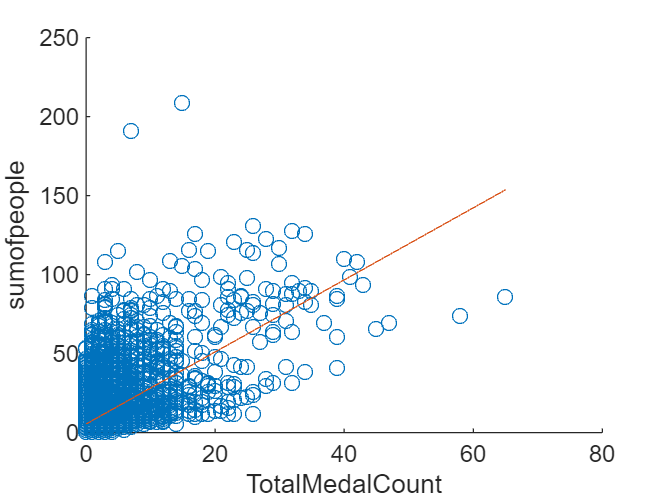

if isnumeric(medalAmountForSports.(SelectedPredictor))
    scatter(medalAmountForSports.(SelectedPredictor),medalAmountForSports.sumofpeople)
    X = [ones(height(medalAmountForSports),1) medalAmountForSports.(SelectedPredictor)];
    b = X\medalAmountForSports.sumofpeople;
    y = X*b;
    hold on
    plot(medalAmountForSports.(SelectedPredictor),y)
    % ylim([0 1])
    hold off
    xlabel(SelectedPredictor)
    ylabel('sumofpeople')
end

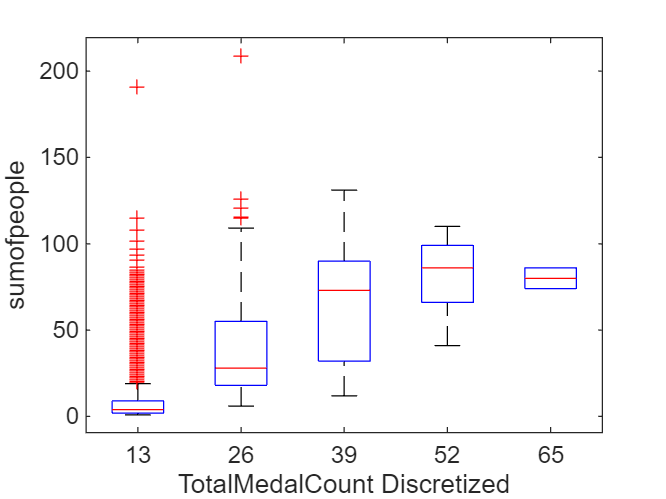

% Choose the number of discretization levels for numeric predictors
NumLevels =5;
if isnumeric(medalAmountForSports.(SelectedPredictor))
    PredictorEdges = linspace(min(medalAmountForSports.(SelectedPredictor)),max(medalAmountForSports.(SelectedPredictor)),NumLevels+1);
    PredictorDiscretized = discretize(medalAmountForSports.(SelectedPredictor),PredictorEdges,'Categorical',string(PredictorEdges(2:end)));
    boxplot(medalAmountForSports.sumofpeople,PredictorDiscretized)
    xlabel([SelectedPredictor ' Discretized'])
    ylabel('sumofpeople')
else
    boxplot(medalAmountForSports.sumofpeople,medalAmountForSports.(SelectedPredictor))
    xlabel(SelectedPredictor)
    ylabel('sumofpeople')
end

data = medalAmountForSports(string(medalAmountForSports.NOC) == "USA",:);
m = max(data.TotalMedalCount);
data.TotalMedalCount = data.TotalMedalCount/m;

NumObs = height(data);
% Reset the random stream state, for reproducibility
% Comment this line out to generate different data partitions each time the example is run
rng('default');
c = cvpartition(NumObs,'HoldOut',0.4);
TrainingInd = training(c);
TestInd = test(c);
mdlTobit = fitLGDModel(data(TrainingInd,:),'tobit','CensoringSide','both','PredictorVars',{'sumofpeople' 'Year' 'Sport'},'ResponseVar','TotalMedalCount');
disp(mdlTobit.UnderlyingModel)

Tobit regression model:
     TotalMedalCount = max(0,min(Y*,1))
     Y* ~ 1 + sumofpeople + Year + Sport

Estimated coefficients:
                                    Estimate         SE         tStat        pValue  
                                   __________    __________    ________    __________

    (Intercept)                        0.6709        0.3797      1.7669       0.07816
    sumofpeople                     0.0025057    0.00044507      5.6298    3.8354e-08
    Year                           -0.0002217    0.00019449     -1.1399       0.25515
    Sport_Archery                    -0.23044      0.061277     -3.7606    0.00020017
    Sport_Art Competitions           -0.41044      0.079882      -5.138    4.7393e-07
    Sport_Athletics                 -0.011206      0.042213    -0.26546       0.79082
    Sport_Badminton                   -1.8119        0.8005     -2.2635      0.024251
    Sport_Baseball and Softball      -0.29248      0.069827     -4.1886    3.5981e-05
    Sport

% latex(disp(mdlTobit.UnderlyingModel))

dataTotalMedalCountPredicted = table;
dataTotalMedalCountPredicted.Observed = data.TotalMedalCount(TestInd) * m;

disp(head(dataTotalMedalCountPredicted));

    Observed
    ________

        0   
        3   
        0   
        2   
        3   
       65   
        2   
        1   



dataTotalMedalCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)) * m; %%%预测用！！！
dataTotalMedalCountPredicted.year = data.Year(TestInd);
dataTotalMedalCountPredicted.sport = string(data.Sport(TestInd));
disp((dataTotalMedalCountPredicted))

    Observed      Tobit       year             sport         
    ________    __________    ____    _______________________

        0            16.45    1896    "Aquatics"             
        3           4.0358    1896    "Shooting"             
        0            1.114    1900    "Fencing"              
        2             2.49    1900    "Sailing"              
        3           5.9047    1900    "Tennis"               
       65           29.449    1904    "Athletics"            
        2           1.4161    1904    "Football"             
        1              NaN    1904    "Lacrosse"             
        3           2.8203    1904    "Weightlifting"        
       17           8.6286    1904    "Wrestling"            
        1           16.794    1906    "Aquatics"             
        6            5.732    1908    "Shooting"             
        0           1.2526    1908    "Tug-Of-War"           
        2           4.4098    1908    "Wrestling"            
       

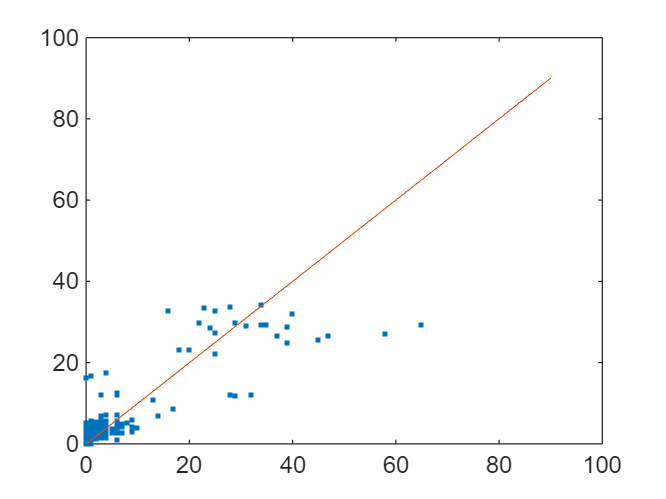

figure;
plot(dataTotalMedalCountPredicted.Observed,dataTotalMedalCountPredicted.Tobit,'.');
hold on
plot(0:0.1:90,0:0.1:90)

er = abs(dataTotalMedalCountPredicted.Observed - dataTotalMedalCountPredicted.Tobit);
er(isnan(er)) = 0;
esr = sum(er.^2/length(er))

esr = 31.0227

% t = mdlTobit.UnderlyingModel.Coefficients.Estimate
% [~,ind] = sort(mdlTobit.UnderlyingModel.Coefficients.Estimate,'descend');
% t = mdlTobit.UnderlyingModel.CoefficientNames(ind)

% processOlympicData('NOC','USA','Sport','Baseball/Softball','Sex','F')
% processOlympicData('NOC','USA','Sport','Baseball/Softball','Sex','M')

% USA predict
data
people2028 = readtable("people2028.xlsx")
% people2028.Year = 2028 * ones(height(people2028),1);
usa2028 = people2028(people2028.NOC == "USA",:)
% usa2028.sumallpeople = usa2028.count
% usa2028.TotalMedalCount = zeros(height(usa2028),1)
total = predict(mdlTobit,usa2028) * m
total(isnan(total)) = 0;
sum(total)